% Step 1: Set up the project structure and load data
clear all; close all; clc;

% Define path to your data files
dataPath = 'CW-Data/';
numUsers = 10;
numFilesPerUser = 6;
samplesPerFile = 36; % Number of samples per file

% Initialize cell array to hold all data
allData = cell(numUsers, numFilesPerUser);

% Load data for each user and each file
for user = 1:numUsers
    for file = 1:numFilesPerUser
        % Adjust filename format as needed
        fileName = sprintf('U%02d_Acc_FreqD_FDay.mat', user); % Update this pattern based on file names
        filePath = fullfile(dataPath, fileName);
        
        % Load .mat file
        loadedData = load(filePath);
        
        % Access the 'Acc_FD_Feat_Vec' variable and store it
        allData{user, file} = loadedData.Acc_FD_Feat_Vec;
    end
end


**Preparing Data for Each Target User**

targetUser = 1; % Change this for each target user (1 through 10)
x = []; % Features matrix
y = []; % Labels vector

for user = 1:numUsers
    label = (user == targetUser); % 1 if target user, otherwise 0
    for file = 1:numFilesPerUser
        features = allData{user, file};
        x = [x; features]; % Append features
        y = [y; repmat(label, samplesPerFile, 1)]; % Append labels
    end
end

**Split Data**

% Split data into training and test sets
cv = cvpartition(size(y,1), 'HoldOut', 0.2);
xTrain = x(training(cv), :);
yTrain = y(training(cv), :);
xTest = x(test(cv), :);
yTest = y(test(cv), :);

**Train a Neural Network Model**

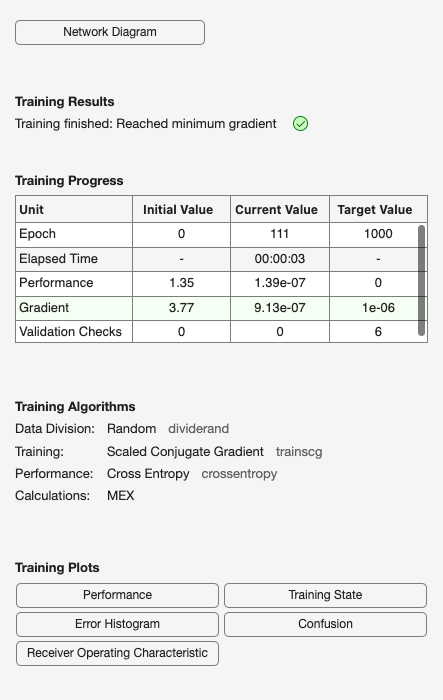

% Define neural network with a hidden layer size of 10 (adjustable)
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize);

% Train the network
[net, tr] = train(net, xTrain', yTrain');

**Test and Evaluate Model Performance**

% Predict on test data
yPred = net(xTest');
yPred = round(yPred'); % Convert predictions to binary output

% Calculate accuracy
accuracy = sum(yPred == yTest) / numel(yTest);
fprintf('Accuracy for User %d: %.2f%%\n', targetUser, accuracy * 100);

Accuracy for User 1: 100.00%



% Calculate confusion matrix and additional metrics
[confusionMat, ~] = confusionmat(yTest, yPred);
TP = confusionMat(2,2);
TN = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);

precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f\n', precision);

Precision: 1.00


fprintf('Recall: %.2f\n', recall);

Recall: 1.00


fprintf('F1 Score: %.2f\n', f1_score);

F1 Score: 1.00


**Repeat for Each User**

results = [];
for targetUser = 1:numUsers
    % Repeat steps 2-6 here for each targetUser
    
    % Log accuracy, precision, recall, F1 score
    results = [results; targetUser, accuracy, precision, recall, f1_score];
end

% Display all results
resultsTable = array2table(results, 'VariableNames', {'User', 'Accuracy', 'Precision', 'Recall', 'F1Score'});
disp(resultsTable);

    User    Accuracy    Precision    Recall    F1Score
    ____    ________    _________    ______    _______

      1        1            1          1          1   
      2        1            1          1          1   
      3        1            1          1          1   
      4        1            1          1          1   
      5        1            1          1          1   
      6        1            1          1          1   
      7        1            1          1          1   
      8        1            1          1          1   
      9        1            1          1          1   
     10        1            1          1          1   

